# Visualizing Pyramid Models of Kernel Density Maps

The following code load the 3D PM matrix created from [Kernel_Density_PM.ipynb](http://localhost:8892/notebooks/Kernel_Density_PM.ipynb) and visualize the PM in a 3D environment.

Visualization is created for the random and clustered point set for comparison.

## 1. Load 3D Matrices

addpath('E:/Projects/Pyramid_model/Matlab_code/function');

path_table = "E:/Projects/Pyramid_model/tables/";
pnts = readtable(path_table+"sim_pnts_random.csv");
pnts_ran = readtable(path_table+"sim_pnts_random.csv");
path_fig = "E:/Projects/Pyramid_model/figures/";
path_fig_r = "E:/Projects/Pyramid_model/figures/review_response/";

warning('off','all')

% ------- load the pyramids of clustered points ------------
array3D_raw = load(path_table + "array3D_raw2_2.mat");
array3D_raw = array3D_raw.vect;

array3D_norm = load(path_table + "array3D_norm2_2.mat");
array3D_norm = array3D_norm.vect;

array3D_z = load(path_table + "array3D_z2_2.mat");
array3D_z = array3D_z.vect;

array3D_pct = load(path_table + "array3D_pct2_2.mat");
array3D_pct = array3D_pct.vect;

% ------- load the pyramids of random points ---------------

array3D_raw_ran = load(path_table + "array3D_raw_ran2_2.mat");
array3D_raw_ran = array3D_raw_ran.vect;

array3D_norm_ran = load(path_table + "array3D_norm_ran2_2.mat");
array3D_norm_ran = array3D_norm_ran.vect;

array3D_z_ran = load(path_table + "array3D_z_ran2_2.mat");
array3D_z_ran = array3D_z_ran.vect;

array3D_pct_ran = load(path_table + "array3D_pct_ran2_2.mat");
array3D_pct_ran = array3D_pct_ran.vect;

% ---------load density peak--------------------------------
max_density = readtable(path_table+"max_density.csv");
max_intensity = readtable(path_table+"max_intensity.csv");

max_density_ran = readtable(path_table+"max_density_ran.csv");
max_intensity_ran = readtable(path_table+"new_point_pattern/max_intensity_ran.csv");

s = size(array3D_norm);
z_scale = 0.75;
z_lim = 100;

## 2. Display Slices (clustered)

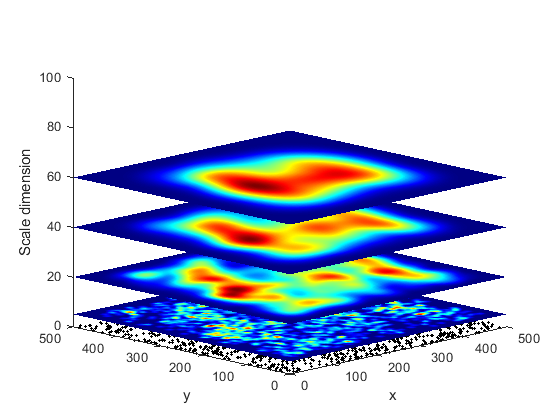

% slice_v =27
cla;
hold off;
scatter3(pnts.x,pnts.y,pnts.y*0,5,'filled','MarkerFaceColor','black');
for slice_v = [5,20,40,60]
    
    hold on;
    
    sl = slice(array3D_norm,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';
    iso_value_s=num2str(slice_v);
    colormap('jet');
    grid off;
    
    view(-45,15);
    xlabel('x')
    ylabel('y')
    zlabel('Scale dimension')
    
    xlim([0 500]);
    ylim([0 500]);
    zlim([0 100]);
    
    %title(strcat('Kernel density (percentile): ',num2str(slice_v)));
    drawnow;
end
exportgraphics(gcf,strcat(path_fig,'KD_slices','.png'),'Resolution',300);
hold off;

## 3. Plot density peak (clustered)

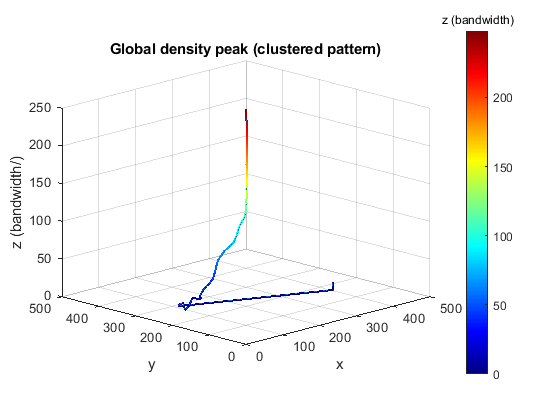

cla;
% ax1 = subplot(3,1,1);
x = max_intensity.x;
y = max_intensity.y;
z = max_intensity.z; 

x1 = max_density.x;
y1 = max_density.y;
z1 = max_density.z;

plot3(x1,y1,z1);
colormap('jet');
patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);

hold on;
%c = sub_lines.z(1).*int16(ones(height(z),1));
%figure;
%h1 = axes;
%plot3(x,y,z,':','Color','#99A3A4','LineWidth',1);

colorbar
view(3)
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');
xlim([0 500]);
ylim([0 500]);
pbaspect([1 1 z_scale]);
view([-60 20]);

% title('Moving trajectory of densest quadrat centroid in the PM');
xlabel('x');
ylabel('y');
zlabel('z (bandwidth/)');
hcb=colorbar;
hcb.Title.String = "z (bandwidth)";
title('Global density peak (clustered pattern)')

ath=-45;
alt = 15;
view(ath,alt);
grid on;
%exportgraphics(gcf,strcat(path_fig_r,'45-15_KDE','.png'),'Resolution',300);
exportgraphics(gcf,strcat(path_fig_r,'peaks_cls2_',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);
hold off;

## 4. Plot density peak (random)

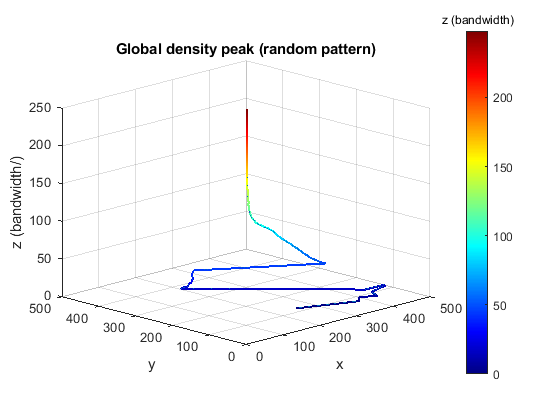

cla;
% ax1 = subplot(3,1,1);

x = max_intensity_ran.x;
y = max_intensity_ran.y;
z = max_intensity_ran.z; 

x1 = max_density_ran.x;
y1 = max_density_ran.y;
z1 = max_density_ran.z;

plot3(x1,y1,z1);
colormap('jet');
patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);

hold on;
%c = sub_lines.z(1).*int16(ones(height(z),1));
%figure;
%h1 = axes;
%plot3(x,y,z,':','Color','#99A3A4','LineWidth',1);

colorbar
view(3)
%set(h1,'XDir','reverse');
%set(h1,'YDir','reverse');
%disp(min(sub_lines.z));
%patch(x, y, z, c,'EdgeColor','interp','FaceColor','none');
xlim([0 500]);
ylim([0 500]);
zlim([0 250]);
pbaspect([1 1 z_scale]);
view([-60 20]);

% title('Moving trajectory of densest quadrat centroid in the PM');
xlabel('x');
ylabel('y');
zlabel('z (bandwidth/)');
hcb=colorbar;
hcb.Title.String = "z (bandwidth)";
title('Global density peak (random pattern)');

ath=-45;
alt = 15;
view(ath,alt);
grid on;
exportgraphics(gcf,strcat(path_fig_r,'peaks_ran2_',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);
hold off;

## 5. Display ISO surface in complete z-axis (clustered)

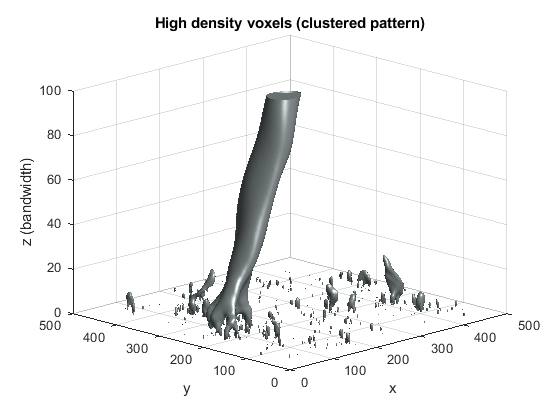

cla reset;
isovalue=0.99;

lim_z=100;

x1 = max_density.x;
y1 = max_density.y;
z1 = max_density.z;

%plot3(x1,y1,z1);
%colormap('jet');
%patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);
%hold on;

array3D = array3D_pct(:,:,1:lim_z);
p = patch(isosurface(array3D,isovalue));
p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';

patch(isocaps(array3D,isovalue),'FaceColor','#99A3A4','EdgeColor','none');

xlim([0 500]);
ylim([0 500]);
zlim([0 lim_z]);
isonormals(array3D,p);
xlabel('x');
ylabel('y');
zlabel('z (bandwidth)');
title('High density voxels (clustered pattern)')

pbaspect([1 1 0.75]);
%daspect([1 1 0.15]);

ath=-45;
alt = 15;
view(ath,alt);

camlight; 
lighting gouraud;
grid on;

exportgraphics(gcf,strcat(path_fig_r,'KD_isosurface_cls',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);

## 6. Display ISO surface in complete z-axis (random)

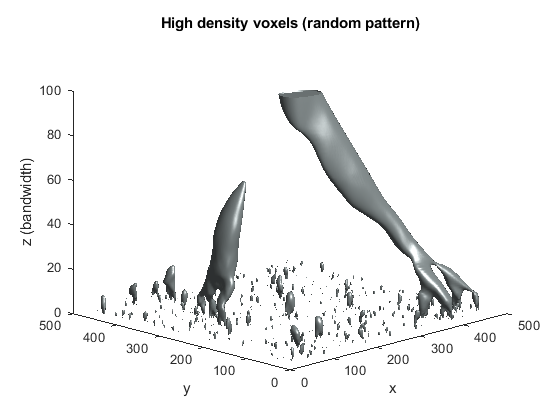

cla reset;
isovalue=0.99;

x1 = max_density_ran.x;
y1 = max_density_ran.y;
z1 = max_density_ran.z;

%plot3(x1,y1,z1);
%colormap('jet');
%patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);
%hold on;

array3D = array3D_pct_ran(:,:,1:lim_z);
p = patch(isosurface(array3D,isovalue));
p.FaceColor = '#99A3A4';
p.EdgeColor = 'none';

patch(isocaps(array3D,isovalue),'FaceColor','#99A3A4','EdgeColor','none');
%colormap(jet);

xlim([0 500]);
ylim([0 500]);
zlim([0 lim_z]);
isonormals(array3D,p);
xlabel('x');
ylabel('y');
zlabel('z (bandwidth)');
title('High density voxels (random pattern)')

pbaspect([1 1 0.75]);
%daspect([1 1 0.15]);

ath = -45;
alt = 15;
view(ath,alt);

camlight; 
lighting gouraud;
exportgraphics(gcf,strcat(path_fig_r,'KD_isosurface_ran',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);
hold off;

## Compute peaks in all levels (clustered)

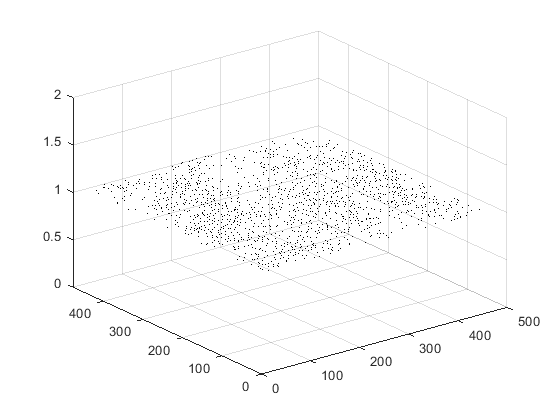

cla reset;
% Create empty table to store peaks in all levels
variable_names_types = [["id", "int16"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]];
% Make table using fieldnames & value types from above
all_coords_cls = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

for z = 1: s(3)
    %z = 1;    
    [cent, varargout]=FastPeakFind(array3D_raw(:,:,z), 0);
    s_cent = size(cent);
    coords = zeros(s_cent(1)/2,4);
    
    for i = 1:s_cent(1)/2
        coords(i,1)=i;
        coords(i,2)=cent(2*i-1);
        coords(i,3)=cent(2*i);
        coords(i,4)=z;
    end
    
    coords = array2table(coords,'VariableNames',{'id','x','y','z'});
    all_coords_cls = vertcat(all_coords_cls,coords);
    %scatter(all_coords.x,all_coords.y,all_coords.z,'MarkerFaceColor','black',"MarkerEdgeColor","none");
    scatter3(all_coords_cls.x,all_coords_cls.y,all_coords_cls.z,2,'filled','MarkerFaceColor','black');
end

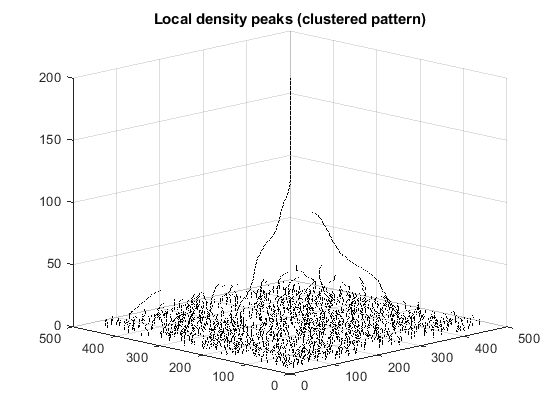

% hold on;
% x1 = max_density.x;
% y1 = max_density.y;
% z1 = max_density.z;
% 
% plot3(x1,y1,z1);
% colormap('jet');
% patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);

xlim([0 500]);
ylim([0 500]);
zlim([0 200]);
title('Local density peaks (clustered pattern)')

ath = -45;
alt = 15;
view(ath,alt);
exportgraphics(gcf,strcat(path_fig_r,'local_peaks_cls-',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);
hold off;

## 6. Compute peaks in all levels (random)

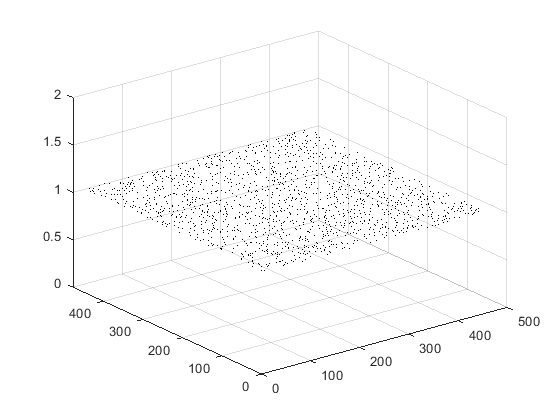

cla reset;
% Create empty table to store peaks in all levels
variable_names_types = [["id", "int16"];["x", "int16"]; ["y", "int16"]; ["z", "int16"]];
% Make table using fieldnames & value types from above
all_coords_ran = table('Size',[0,size(variable_names_types,1)],... 
	'VariableNames', variable_names_types(:,1),...
	'VariableTypes', variable_names_types(:,2));

for z = 1: s(3)
    %z = 1;    
    [cent, varargout]=FastPeakFind(array3D_raw_ran(:,:,z), 0);
    s_cent = size(cent);
    coords = zeros(s_cent(1)/2,4);
    
    for i = 1:s_cent(1)/2
        coords(i,1)=i;
        coords(i,2)=cent(2*i-1);
        coords(i,3)=cent(2*i);
        coords(i,4)=z;
    end
    
    coords = array2table(coords,'VariableNames',{'id','x','y','z'});
    all_coords_ran = vertcat(all_coords_ran,coords);
    %scatter(all_coords.x,all_coords.y,all_coords.z,'MarkerFaceColor','black',"MarkerEdgeColor","none");
    scatter3(all_coords_ran.x,all_coords_ran.y,all_coords_ran.z,2,'filled','MarkerFaceColor','black');
end

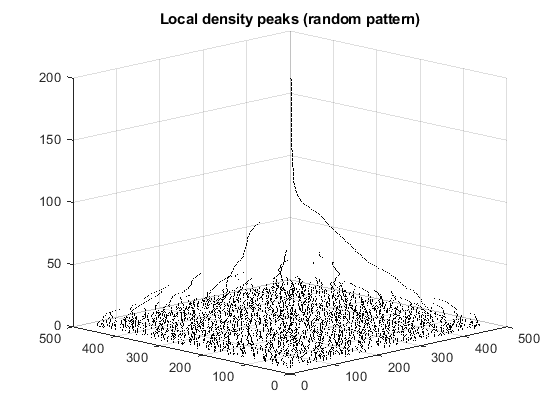

% hold on;
% x1 = max_density.x;
% y1 = max_density.y;
% z1 = max_density.z;
% 
% plot3(x1,y1,z1);
% colormap('jet');
% patch([x1.' nan],[y1.' nan],[z1.' nan],[z1.' nan],'FaceColor','none','EdgeColor','interp','LineWidth',1.5);

xlim([0 500]);
ylim([0 500]);
zlim([0 200]);
title('Local density peaks (random pattern)')

ath = -45;
alt = 15;
view(ath,alt);
exportgraphics(gcf,strcat(path_fig_r,'local_peaks_ran-',num2str(ath),'-',num2str(alt),'.png'),'Resolution',300);
hold off;

## 7. Slices of Local Peaks (Random)

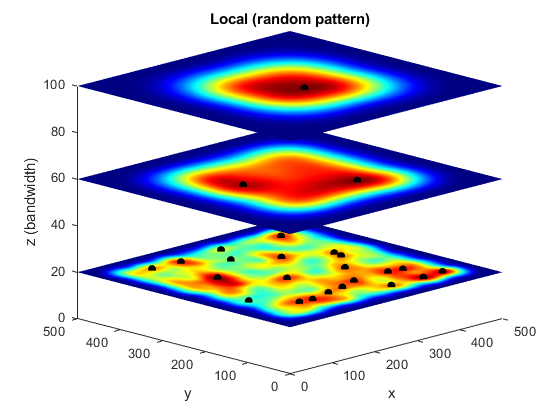

cla;
lim_z=50;

xlim([0 500]);
ylim([0 500]);
zlim([0 100]);
view(-45,15);
xlabel('x');
ylabel('y');
zlabel('z (bandwidth)');
pbaspect([1 1 0.8]);
%daspect([1 1 0.8]);
hold on;

for slice_v = [20 60 100]
    sl = slice(array3D_norm_ran,[],[],slice_v,'EdgeColor','none');
    sl.EdgeColor = 'none';

    colormap('jet');
    grid off;
    
    all_coords_lv = all_coords_ran(all_coords_ran.z==slice_v,:);
    scatter3(all_coords_lv.x,all_coords_lv.y,all_coords_lv.z,'filled','MarkerFaceColor','black');
    
    %title(strcat('Kernel density (percentile): ',num2str(slice_v)));
    drawnow;
end
exportgraphics(gcf,strcat(path_fig,'peaks_',num2str(ath),num2str(alt),'_slices.png'),'Resolution',300);
hold off;

## 8. Numbers of peaks at different levels (clustered (blue) vs random (red))

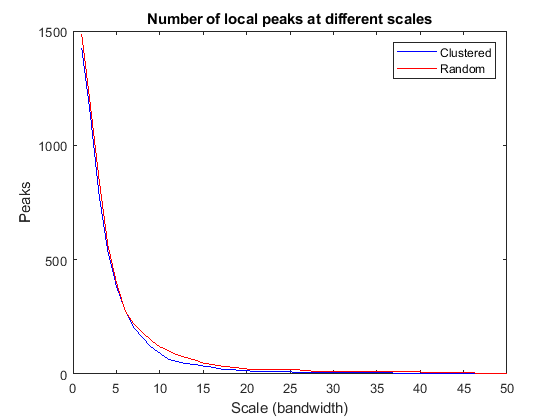

close all;
peak_freq_cls = tabulate(all_coords_cls.z); 
peak_freq_ran = tabulate(all_coords_ran.z); 
xlim2 = 50;
plot(peak_freq_cls(1:xlim2,1),peak_freq_cls(1:xlim2,2),'b',peak_freq_ran(1:xlim2,1),peak_freq_ran(1:xlim2,2),'r');
title('Number of local peaks at different scales');
xlabel('Scale (bandwidth)');
ylabel('Peaks');
legend('Clustered','Random');
exportgraphics(gcf,strcat(path_fig_r,'line_chart_local_peaks.png'),'Resolution',300);

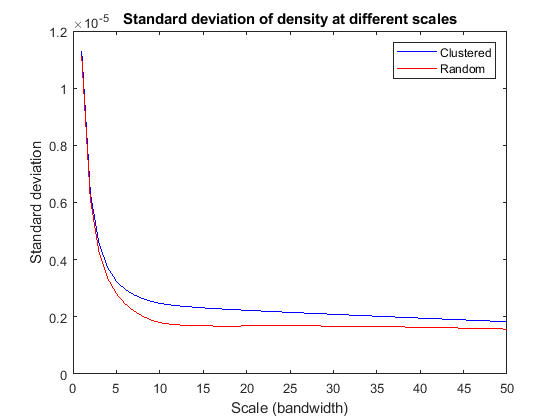

std_cls = std(array3D_raw,0,[1,2]);
std_cls = std_cls(:);

std_ran = std(array3D_raw_ran,0,[1,2]);
std_ran = std_ran(:);

plot(1:xlim2,std_cls(1:xlim2),'b',1:xlim2,std_ran(1:xlim2),'r');
title('Standard deviation of density at different scales');
xlabel('Scale (bandwidth)');
ylabel('Standard deviation');
legend('Clustered','Random');
exportgraphics(gcf,strcat(path_fig_r,'line_chart_st_dv.png'),'Resolution',300);
hold off;

## 9. Calculate horizontal position between each pair of peaks (random vs clustered)

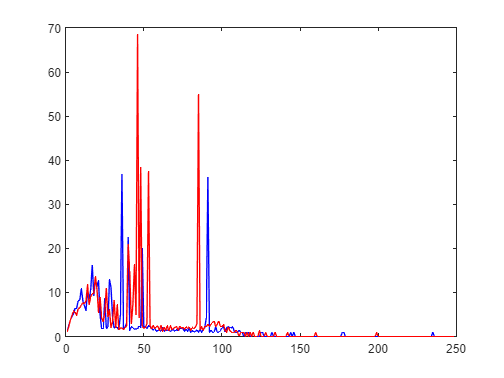

% Plot histogram of distance of peak shifts
% link adjacent peaks to pairs
linked_peaks_ran = link_peaks_fun(all_coords_ran,s(3));
linked_peaks_cls = link_peaks_fun(all_coords_cls,s(3));

mean_dist_ran = grpstats(linked_peaks_ran,{'z'});
mean_dist_ran = mean_dist_ran(:,{'z','mean_dist'});

mean_dist_cls = grpstats(linked_peaks_cls,{'z'});
mean_dist_cls = mean_dist_cls(:,{'z','mean_dist'});

plot(mean_dist_cls.z,mean_dist_cls.mean_dist,'b',mean_dist_ran.z,mean_dist_ran.mean_dist,'r');

## 10. Plot histogram of peak shifting distances

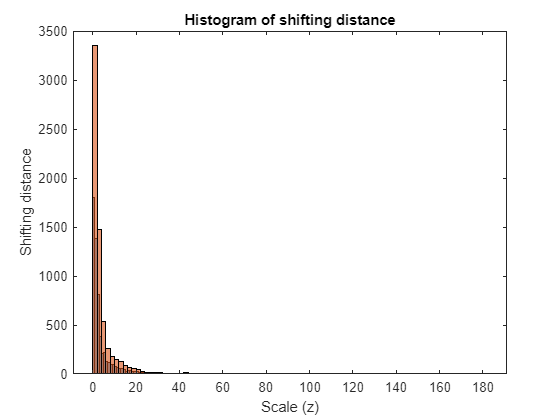

histogram(linked_peaks_cls.dist);
hold on;
histogram(linked_peaks_ran.dist);
title('Histogram of shifting distance');
xlabel('Scale (z)');
ylabel('Shifting distance');
hold off;

## 11. Calculate horizontal distance between each pair (random)

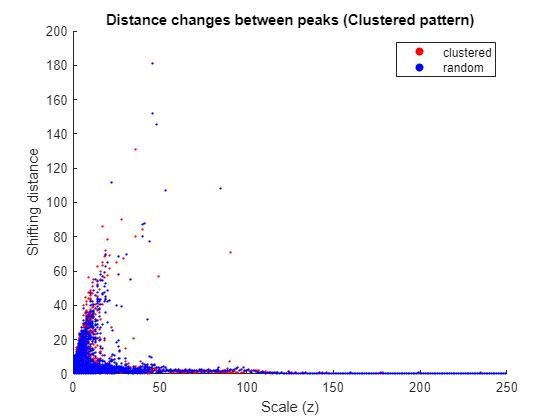

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



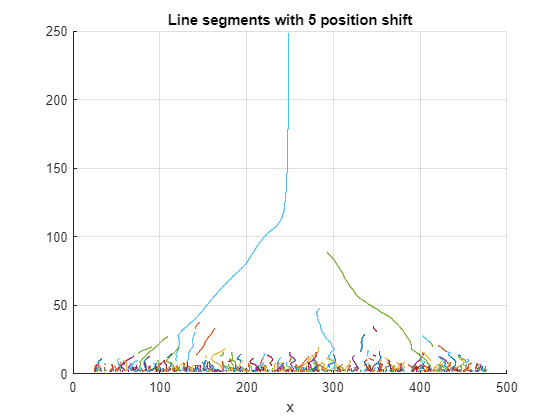

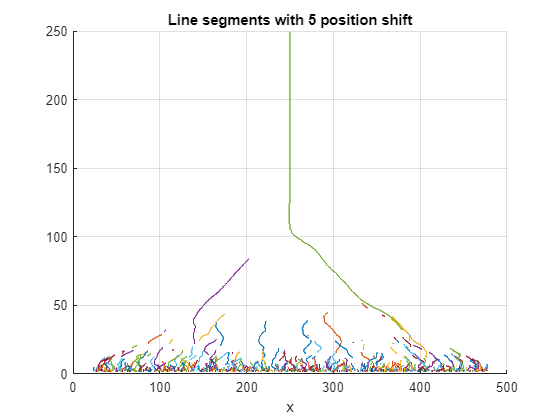

scatter(linked_peaks_cls.z,linked_peaks_cls.dist,3,'filled','MarkerEdgeColor','none','MarkerFaceColor','r');
hold on;
scatter(linked_peaks_ran.z,linked_peaks_ran.dist,3,'filled','MarkerEdgeColor','none','MarkerFaceColor','b');

title('Distance changes between peaks (Clustered pattern)');
xlabel('Scale (z)');
ylabel('Shifting distance');
legend('clustered','random');
hold off;